A function called ***T******hinning*** has been defined separately defined to perform the skeletonization as seen in this exercise. The Thinning function is found in the same directory as this code.

The Thining Function contains all the step-wise process for the skeletonization as defined by the assignment.

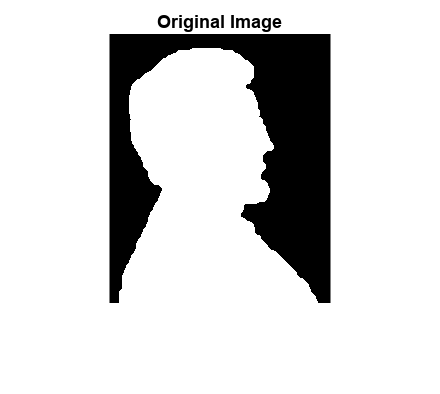

clear; %clear memory
clc; %clear command window

%These are for the images without noise
I1 = imread('images/Fig0914(a)(licoln from penny).tif');
I2 = imread('images/Fig1108(a)(mapleleaf).tif');
I3 = imread('images/Fig1111(a)(triangle).tif');
I4 = imread('images/Fig1111(b)(square).tif');
I5 = imread('images/Fig1116(leg_bone).tif');
I6 = imread ('images/chromosome.TIF');

%These are the images with noise that would require a filter
I7= imread('images/Fig1105(a)(noisy_stroke).tif'); 
I8 = im2double(imread('images/Chromosome2.jpg'));

%Display the original lincoln from penny image
figure,imshow (I1); title ('Original Image')

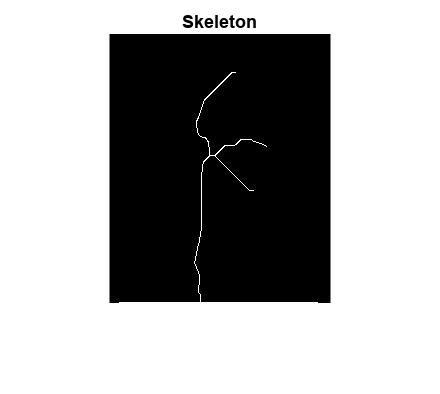

%We call the thinning function that we have created to perform
%skeletonization on the lincoln from penny image
Thinning(I1) 

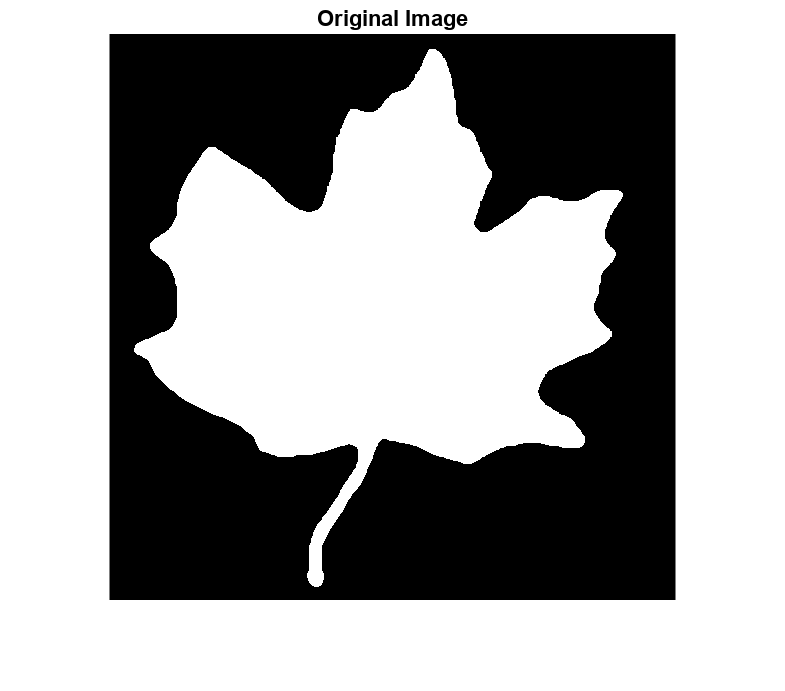

%Display the original Maple leaf Image
figure,imshow (I2); title ('Original Image')

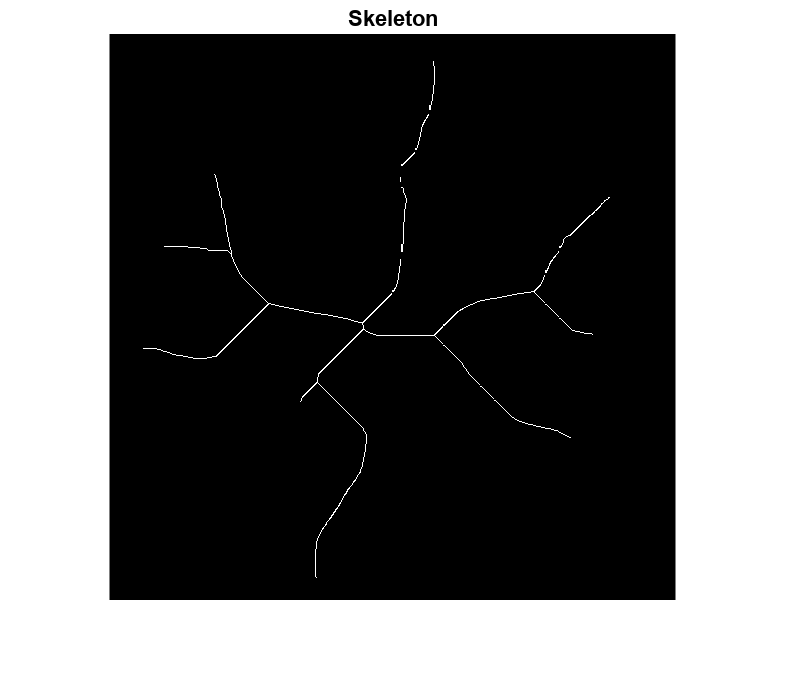

%Perform skeletonization on Maple leaf using the function thinning we have created
Thinning(I2) 

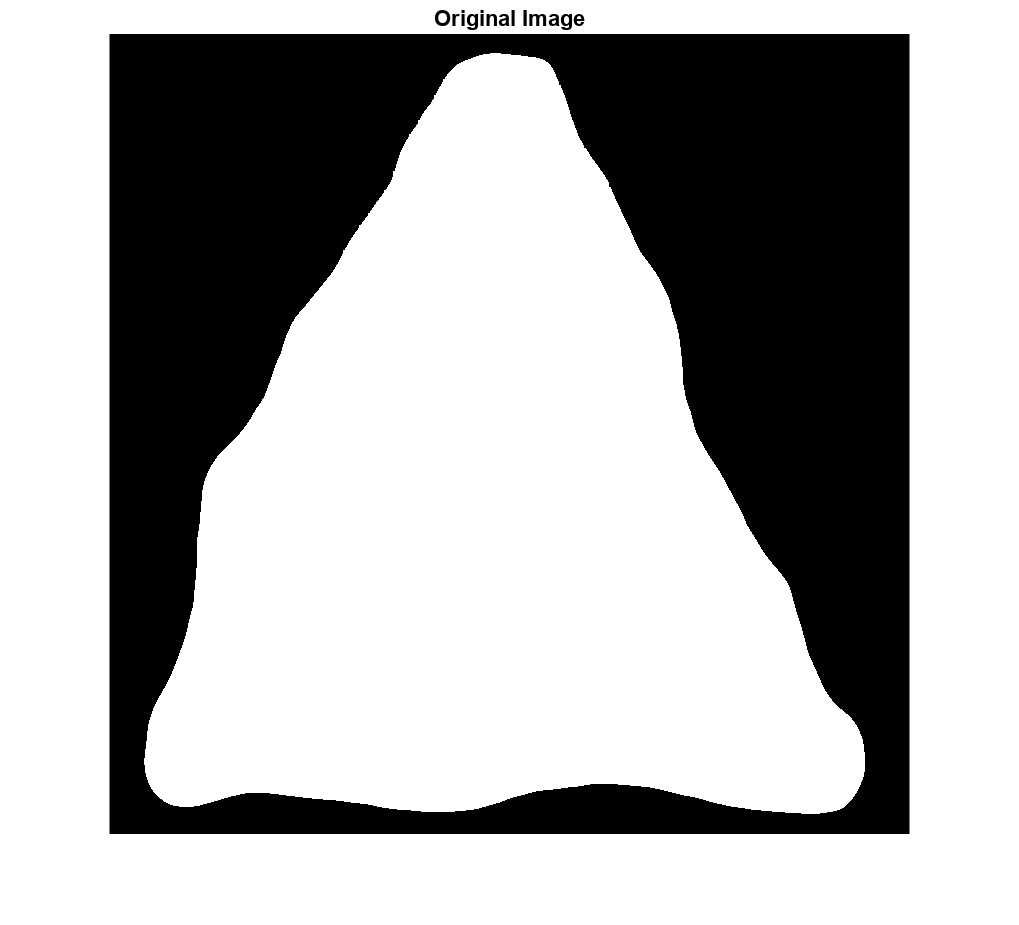

%Display the original triangle image
figure,imshow (I3); title ('Original Image')

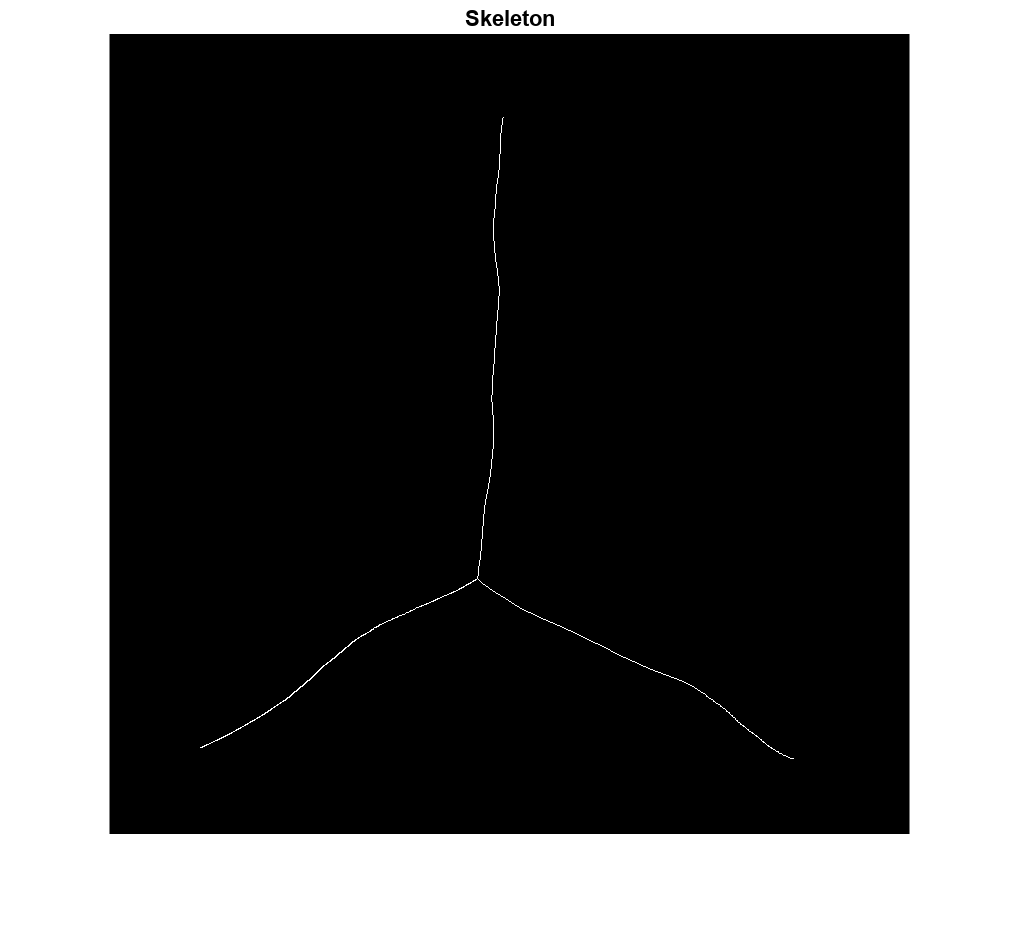

%Perform skeletonization on the triangle image
Thinning(I3) 

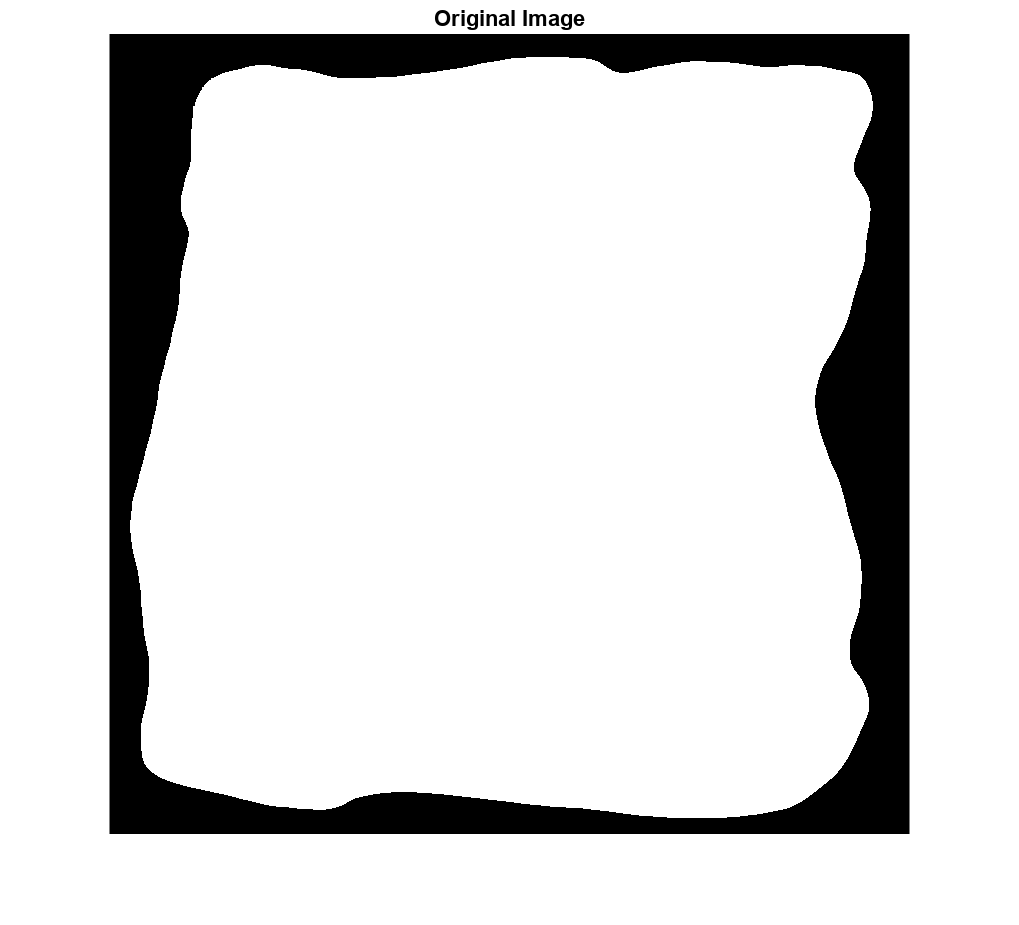

%Display the original square image
figure,imshow (I4); title ('Original Image')

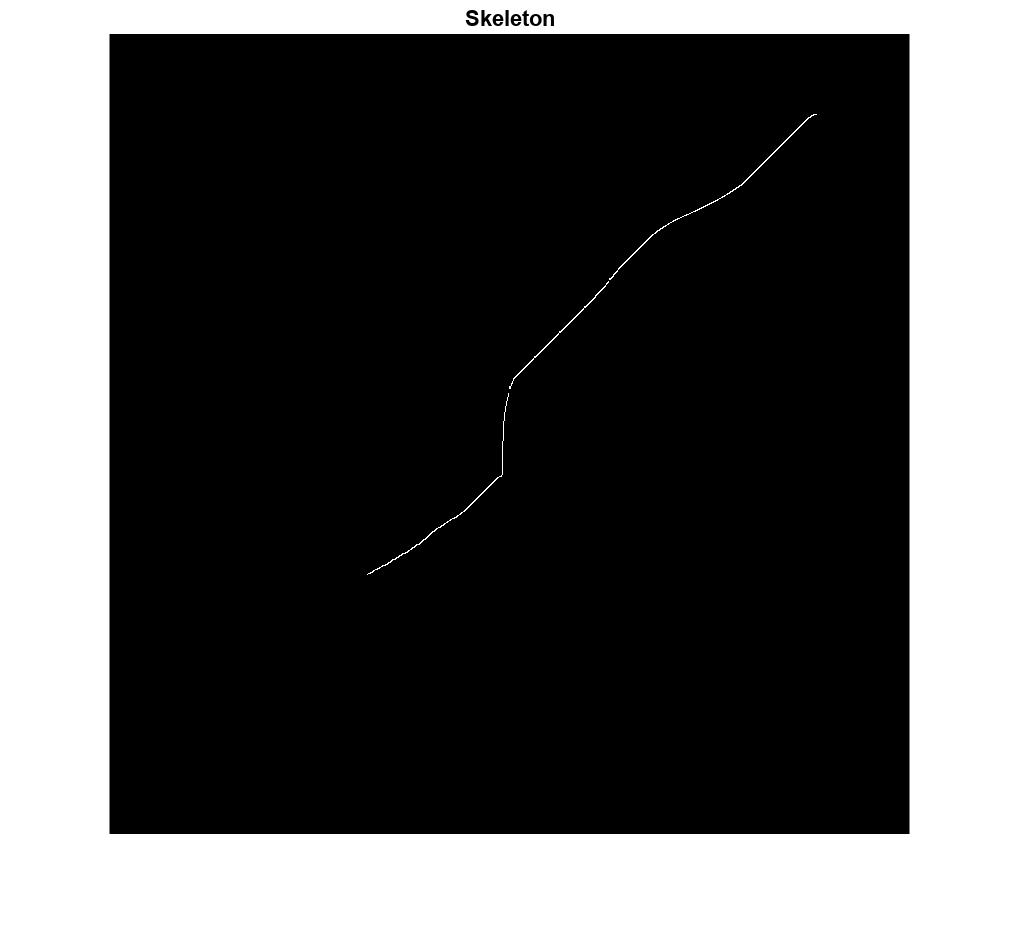

%Perform skeletonization on the square image
Thinning(I4) 

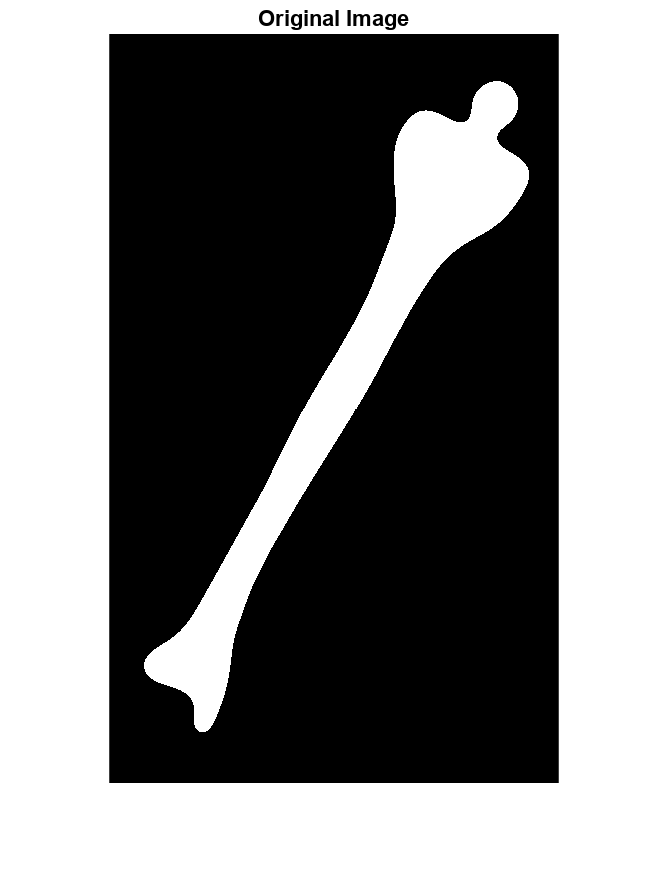

%Display the original leg_bone image
figure,imshow (I5); title ('Original Image')

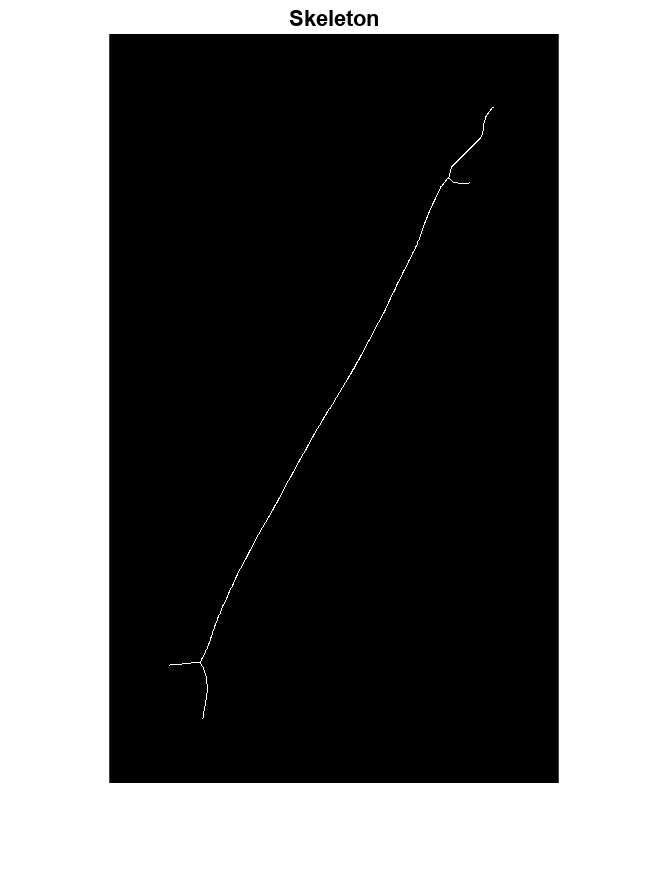

%Perform skeletonization on the leg bone image
Thinning(I5) 

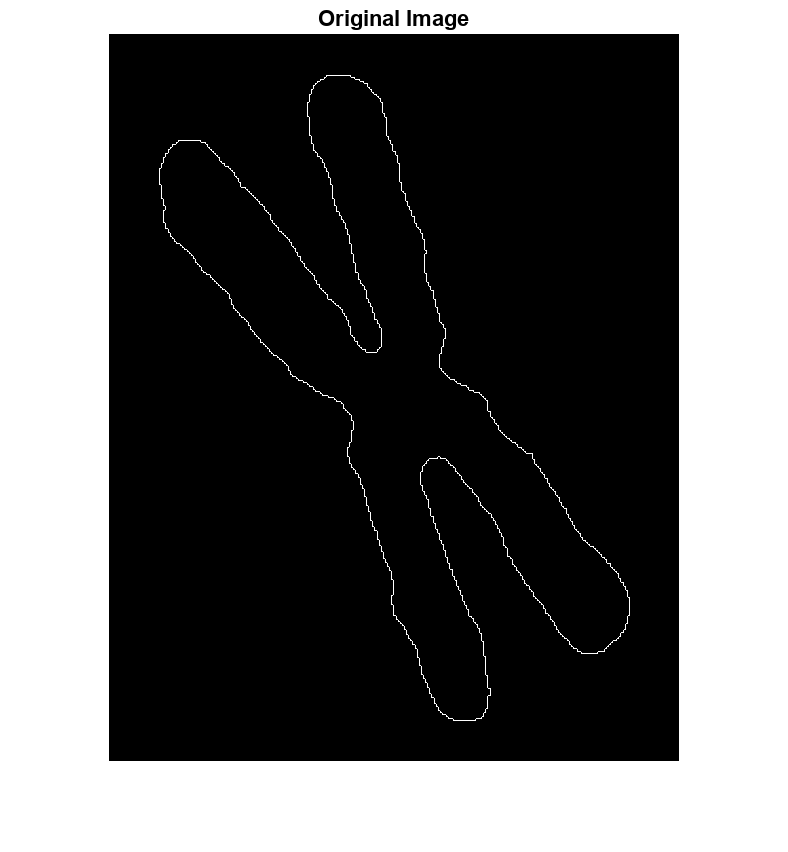

%Display the chromosome.TIF image
figure,imshow (I6); title ('Original Image')

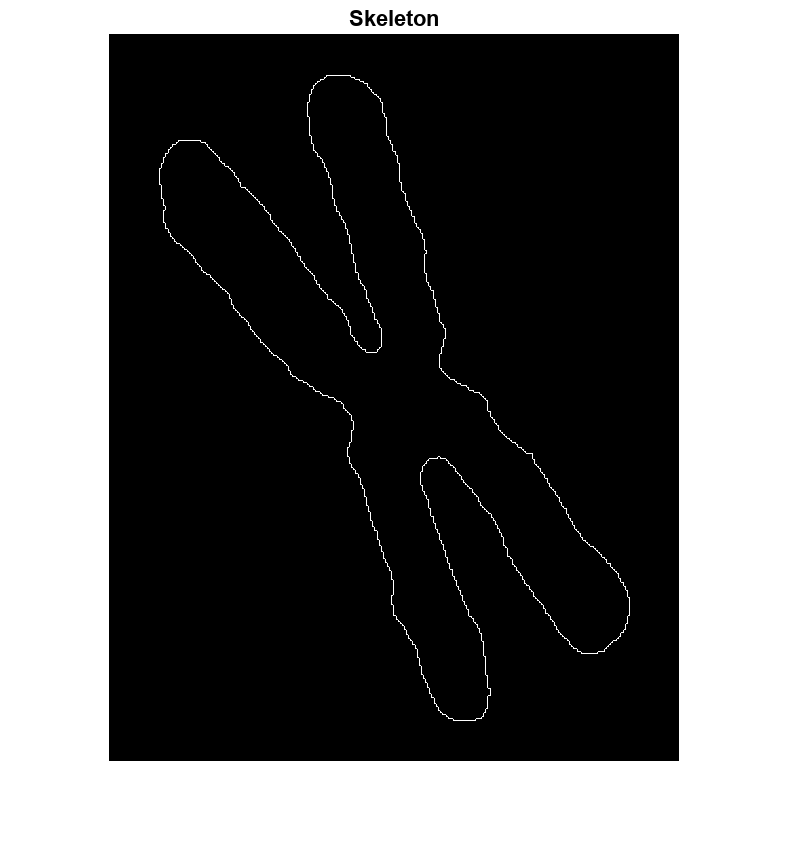

%Perform skeletonization on the chromosome.TIF image
Thinning (I6)

**This code is for images with noise needing a kernel for filtering**

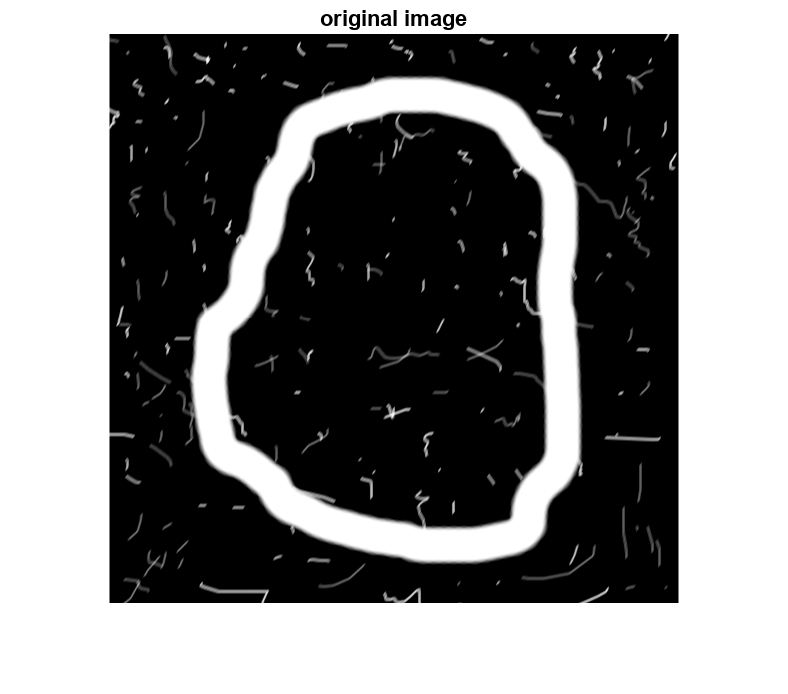

%Display the original noisy stroke image
imshow (I7); title ('original image')

Defining the Kernel for filtering

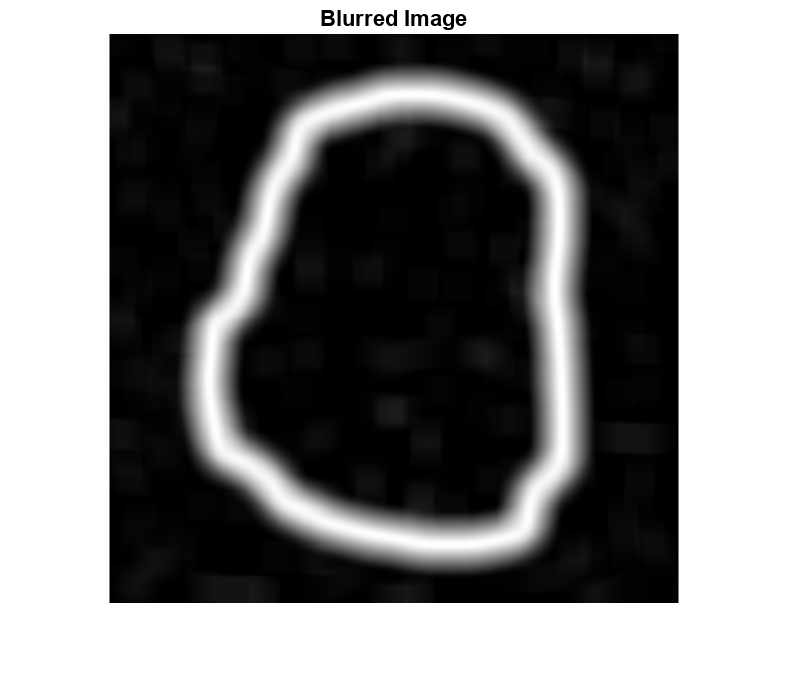

%Define the Kernel for noisy image
windowWidth = 30; 
kernel = ones(windowWidth) / windowWidth ^ 2;
blurredImage = imfilter(I7, kernel); 
%Display blurred Image
imshow(blurredImage); title ('Blurred Image');

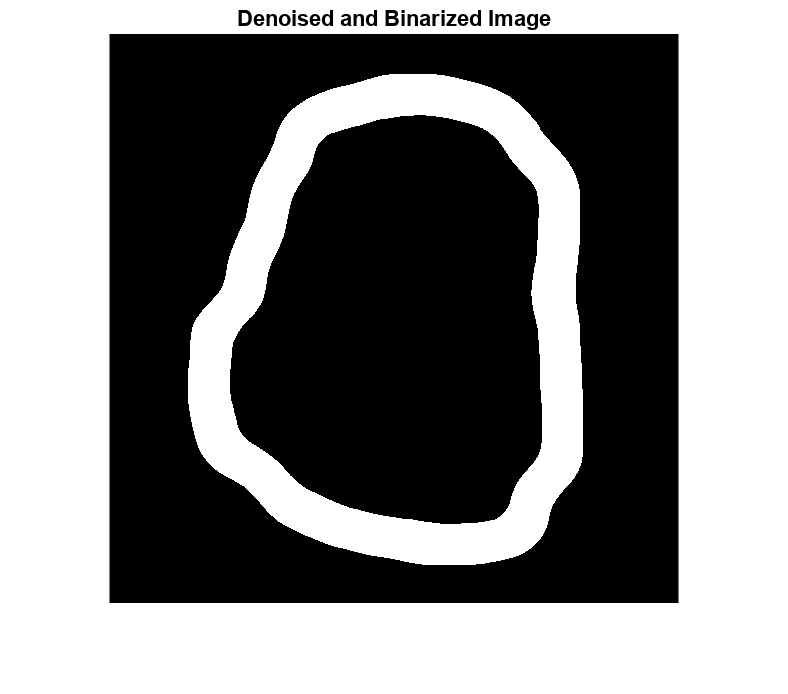

%Imbinarize the Image
J=imbinarize(blurredImage);
%Display Denoised and Binarized Image
imshow(J);title ('Denoised and Binarized Image')

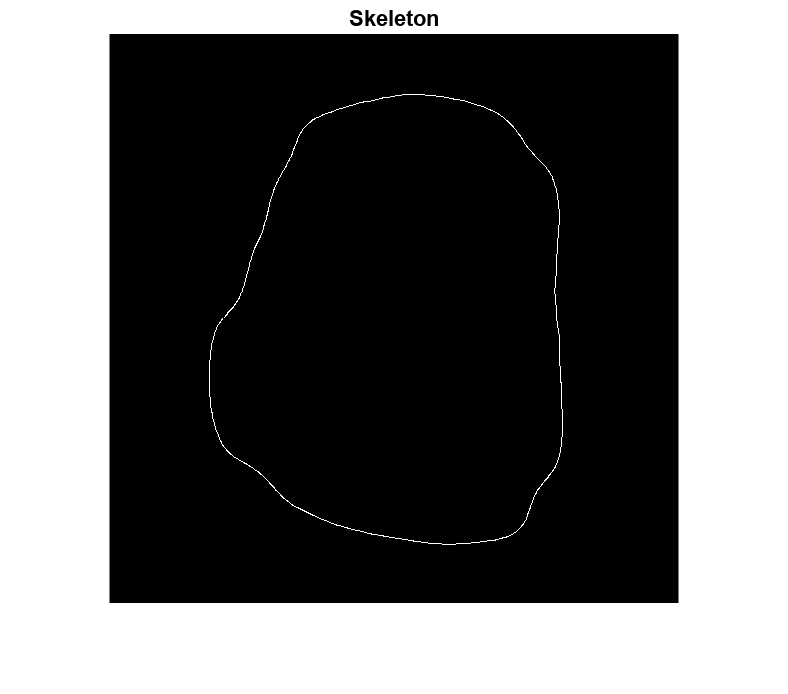

%Perform skeletonization on the noisy stroke image
Thinning (J)

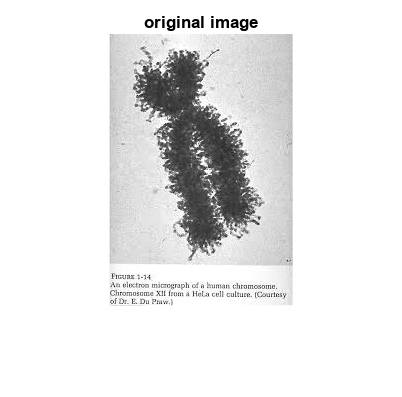

%Display original Chromosome2.jpg
figure,imshow(I8); title ("original image")

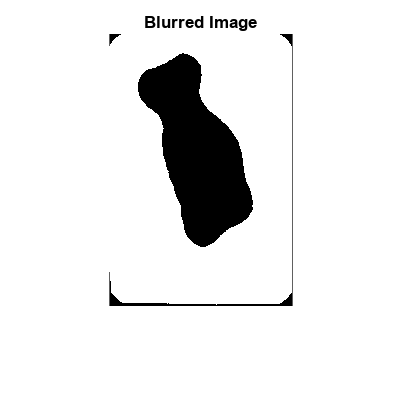

%Convert the image from rgb to grayscale image
Igray = rgb2gray(I8);
%Imbinarize the image
J=imbinarize(Igray);
%Define the Kernel 
windowWidth =28; 
kernel = ones(windowWidth) / windowWidth ^ 2;
b= imfilter(J, kernel); 
%Display the blurred Image
imshow(b);title('Blurred Image')

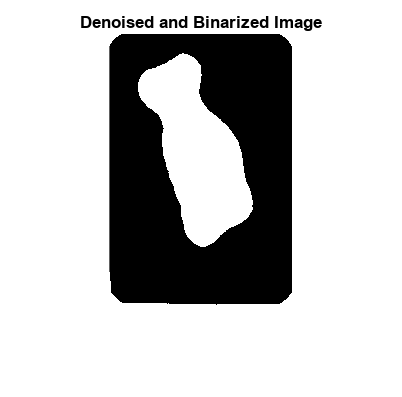

%Find the complement of the blurred image
D = (not(b));
%Display the Denoised and Binarized Image
imshow(not(b));title('Denoised and Binarized Image')

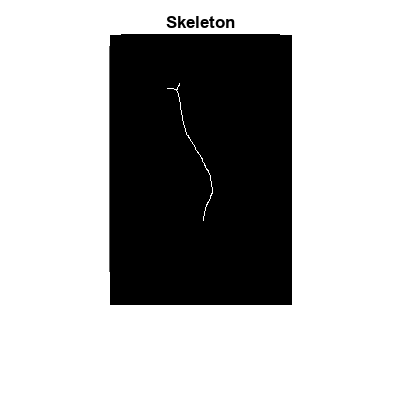

%Perform skeletonization on the binarized and denosised Chromosome2.jpg
%image
Thinning (D)

# Problem 2

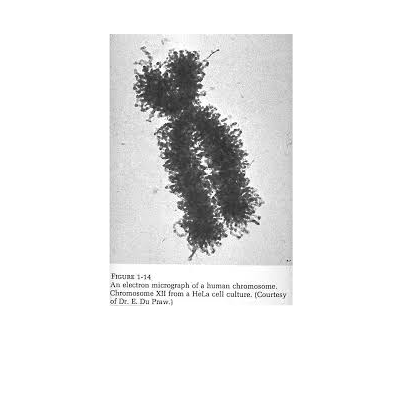

%Load the Chromosome Image
I8 = im2double(imread('images/Chromosome2.jpg'));
% Display the Chromosome2.jpg image
figure, imshow(I8);

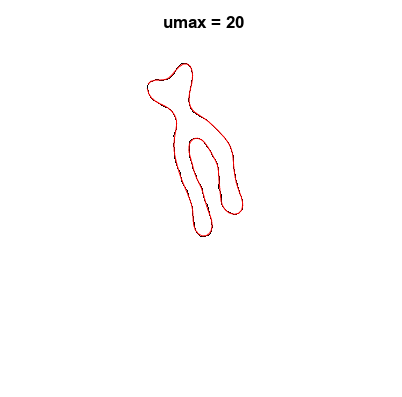

% Convert image to grayscale and invert colors

I8_gray = rgb2gray(I8);
I8_inverted = 1 - im2double(I8_gray);

% Apply Gaussian filter to smoothen the image
gaussian_filter = fspecial('gaussian', 25, 15);
I8_filtered = imfilter(I8_inverted, gaussian_filter, 'replicate');

% Convert to binary using a threshold based on Otsu's method
I8_binary = imbinarize(I8_filtered, 1.7 * graythresh(I8_filtered));

% Trace the boundary of the binary object
[rows, cols] = find(I8_binary ~= 0);
boundary = bwtraceboundary(I8_binary, [rows(1), cols(1)], 'N');

% Resample the boundary to 128 points and apply FFT
sample_factor = length(boundary) / 128;
dist = 1;
for i = 1:128
    complex_points(i) = boundary(round(dist), 2) + 1j * boundary(round(dist), 1);
    dist = dist + sample_factor;
end
complex_spectrum = fft(complex_points);

% Set high frequency components to zero
umax = 20;
approx_spectrum = complex_spectrum;
for u = 1:128
    if u > umax && u < 128 - umax
        approx_spectrum(u) = 0;
    end
end

% Apply inverse FFT to obtain the approximated boundary
approx_points = ifft(approx_spectrum);

% Display image with the boundary overlaid in red colour
imshow(imcomplement(bwperim(I8_binary)));title (" umax = " + umax)
hold on, plot(approx_points, 'r');

**B. Transformation/invariance properties of the Fourier descriptors**

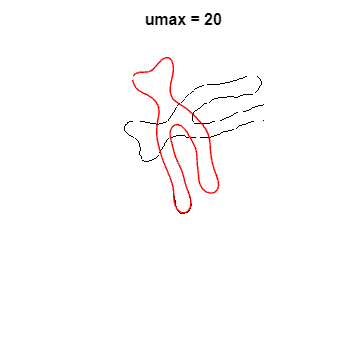

I8 = im2double(imread('images/Chromosome2.jpg'));
% Convert image to grayscale and invert colors
I8_gray = rgb2gray(I8);
I8_inverted = 1 - im2double(I8_gray);

% Apply Gaussian filter to smoothen the image
gaussian_filter = fspecial('gaussian', 25, 15);
I8_filtered = imfilter(I8_inverted, gaussian_filter, 'replicate');

% Convert to binary using a threshold based on Otsu's method
I8_binary = imbinarize(I8_filtered, 1.7 * graythresh(I8_filtered));

% Trace the boundary of the binary object
[rows, cols] = find(I8_binary ~= 0);
boundary = bwtraceboundary(I8_binary, [rows(1), cols(1)], 'N');

% Resample the boundary to 128 points and apply FFT
sample_factor = length(boundary) / 128;
dist = 1;
for i = 1:128
    complex_points(i) = boundary(round(dist), 2) + 1j * boundary(round(dist), 1);
    dist = dist + sample_factor;
end
complex_spectrum = fft(complex_points);

% Set high frequency components to zero
umax = 20;
approx_spectrum = complex_spectrum;
for u = 1:128
    if u > umax && u < 128 - umax
        approx_spectrum(u) = 0;
    end
end

% Apply inverse FFT to obtain the approximated boundary
approx_points = ifft(approx_spectrum);

% Display image with the boundary overlaid in red colour
imshow(imcomplement(bwperim(rot90(I8_binary))));title (" umax = " + umax)
hold on, plot(approx_points, 'r');